Homework #02

## 1a

A=[ -5.868, -7.551, 0.158;
-7.551, 3.83, 0.426;
0.158, 0.426, 6.038];

[1a pic]

1a continued)

v1=[-0.8733; -0.217; 0.4361];

v=v1;
for i = 2:1:50
    v=A*v;
    v=v./norm(v);
    if i<6
        disp([num2str(i) 'th iteration:'])
        disp(v)
    end
end

2th iteration:


    0.7290
    0.6347
    0.2564



3th iteration:


   -0.9310
   -0.3056
    0.1994



4th iteration:


    0.7919
    0.6034
    0.0940



5th iteration:


   -0.9258
   -0.3657
    0.0957



e1=v;
disp('50th iteration:')

50th iteration:


disp(e1)

    0.8772
    0.4796
   -0.0214




lambda1 = (A*e1) ./ e1;
lambda1 = mean(lambda1(:));
disp('lambda for 50th iteration:')

lambda for 50th iteration:


disp(lambda1)

  -10.0004



## 1b

Hotelling deflation can be used for normal (and symmetric) matrices since they have eigenvectors that are orthogonal and Hotelling deflation needs $\mathbf{e_1} \cdot \mathbf{e_2}$ = 0. The Wielandt deflation can be used for non-normal matrices/when the eigenvectors are not orthogonal.

## 1c

A=[ -5.868, -7.551, 0.158;
-7.551, 3.83, 0.426;
0.158, 0.426, 6.038];

B=[ 4.828, 2.053, -0.002;
-4.651, 3.21, -7.63;
-1.889, -11.09, -4.038];

disp('checking if A is normal:')

checking if A is normal:


disp(A*A')

   91.4760   15.4562   -3.1899
   15.4562   71.8680    3.0107
   -3.1899    3.0107   36.6639



disp(A'*A)

   91.4760   15.4562   -3.1899
   15.4562   71.8680    3.0107
   -3.1899    3.0107   36.6639



 A looks normal (looks symmetric) and we can check this from `A*A'` and `A'*A` being equal, so we can use Hotelling deflation

disp('checking if B is normal:')

checking if B is normal:


disp(B*B')

   27.5244  -15.8496  -31.8798
  -15.8496   90.1528    3.9968
  -31.8798    3.9968  142.8619



disp(B'*B)

   48.5097   15.9312   43.1053
   15.9312  137.5070   20.2850
   43.1053   20.2850   74.5223



B is not normal since `B*B'` isn't equal to `B'*B`, so we can not use Hotelling deflation.

[1c 2nd largest eigenvalue Hotelling matrix pic]

[1c 2nd largest eigenvalue 1st iteration pic]

A_e2=[1.8275 -3.3436, -0.0296; 
    -3.3436, 6.13, 0.3235;
    -0.0296, 0.3235, 6.0426];
e2_v1=[-0.215; 0.430; 0.877];

v=e2_v1;
for i = 2:1:50
    v=A_e2*v;
    v=v./norm(v);
    if i<6
        disp([num2str(i) 'th iteration:'])
        disp(v)
    end
end

2th iteration:


   -0.2728
    0.5345
    0.7999



3th iteration:


   -0.3258
    0.6273
    0.7073



4th iteration:


   -0.3688
    0.7017
    0.6097



5th iteration:


   -0.4008
    0.7561
    0.5174



e2=v;
disp('e2 50th iteration:')

e2 50th iteration:


disp(e2)

   -0.4714
    0.8689
    0.1507




lambda2 = (A_e2*e2) ./ e2;
lambda2 = mean(lambda2(:));
disp('lambda 2 for 50th iteration:')

lambda 2 for 50th iteration:


disp(lambda2)

    8.0001



[1c pic for A_e3 and first iteration again]

A_e3=[0.0496, -0.0665, 0.5389;
    -0.0665, 0.0895, -0.7243;
    0.5389, -0.7243, 5.8608];
e3_v1=[0.0901; -0.123; 0.989];

v=e3_v1;
for i = 2:1:50
    v=A_e3*v;
    v=v./norm(v);
    if i<6
        disp([num2str(i) 'th iteration:'])
        disp(v)
    end
end

2th iteration:


    0.0909
   -0.1221
    0.9883



3th iteration:


    0.0909
   -0.1221
    0.9883



4th iteration:


    0.0909
   -0.1221
    0.9883



5th iteration:


    0.0909
   -0.1221
    0.9883



e3=v;
disp('e3 50th iteration:')

e3 50th iteration:


disp(e3)

    0.0909
   -0.1221
    0.9883




lambda3 = (A_e3*e3) ./ e3;
lambda3 = mean(lambda3(:));
disp('lambda 3 for 50th iteration:')

lambda 3 for 50th iteration:


disp(lambda3)

    5.9999



## 1d

B=[ 4.828, 2.053, -0.002;
-4.651, 3.21, -7.63;
-1.889, -11.09, -4.038];

Yes since Wielandt deflation can be used for non-normal matrices like B.

% first eigenvector
v=ones(3,1);
for i = 1:1:50
    v=B*v;
    v=v./norm(v);
end
e1=v;
disp('first eigenvector:')

first eigenvector:


disp(e1)

   -0.0665
    0.4813
    0.8740





lambda1 = (B*e1) ./ e1;
lambda1 = mean(lambda1(:));
disp('first eigenvalue:')

first eigenvalue:


disp(lambda1)

  -10.0014



[1d continued pic Wielandt matrix and first iteration]

B_e2 = [4.9718, 2.8970, 0.3053;
   -5.6913, -2.8976, -9.8538;
   -3.7780, -22.1801, -8.0760];
e2_v1=[0.207; -0.466; -0.860];
        
v=e2_v1;
for i = 2:1:50
    v=B_e2*v;
    v=v./norm(v);
    if i<6
        disp([num2str(i) 'th iteration:'])
        disp(v)
    end
end

2th iteration:


   -0.0313
    0.4639
    0.8853



3th iteration:


    0.0729
   -0.4945
   -0.8661



4th iteration:


   -0.0662
    0.4741
    0.8779



5th iteration:


    0.0659
   -0.4848
   -0.8721



e_defl2=v;
lambda_defl2 = (B_e2*e_defl2) ./ e_defl2;
lambda_defl2 = nanmean(lambda_defl2(:));

[max_val, max_idx] = max(abs(e1));
e_1p=e1(max_idx, 1);
b_p=B(max_idx, :);

e2=e_defl2 + ((b_p*e_defl2 ./ (lambda_defl2 - lambda1))*(e1./e_1p))

e2 =    -0.1330
    0.9626
    1.7480


## 1e

disp('For A:')

For A:


[V_A,D_A]=eig(A)

V_A =     0.8772   -0.0908    0.4714
    0.4796    0.1221   -0.8689
   -0.0214   -0.9884   -0.1507


D_A =   -10.0002         0         0
         0    5.9999         0
         0         0    8.0003


The eigenvectors (V_A) are along the same vectors and the eigenvalues (D_A) are equal from power method as those from the Matlab eig() function. For A, they do in fact converge with the power method and arrive at the correct eigenvalues/vectors. This is possible because each of the eigenvalues here are different in absolute value and each eigenvalue is significantly greater than the next eigenvalue in absolute value.

## 2

Q=[ 0   0   0   1/3 0   1/3 0   1/3;
    0   0   1/2 0   0   0   1/2 0;
    0   0   0   0   1   0   0   0;
    0   0   0   0   1/2 0   1/2 0;
    0   0   0   0   0   0   0   0;
    0   0   0   1/3 1/3 0   0   1/3;
    0   0   1   0   0   0   0   0;
    0   0   0   0   1   0   0   0];
[n, ~]=size(Q);


$$\hat{Q}=Q+\frac{1}{n}ed^{T}$$


e_vec = sum(Q,2)==0;
d_vec = ones(n, 1);
Q_hat=Q + ((1/n).* e_vec * d_vec.');


$$\hat{\hat{Q}}=\alpha\hat{Q}+(1-\alpha)\frac{1}{n}dd^T$$


tel=0.85;
Q_hathat=(tel*Q_hat) + ((1-tel).*(1/n).*d_vec*d_vec.');

% finding largest eigenvector of Q_hathat.' with power method
x = ones(n, 1);
for i=1:1:50
    x=Q_hathat.'*x;
    x=x./norm(x);
end
disp(x)

    0.1264
    0.1264
    0.4084
    0.2082
    0.7849
    0.1622
    0.2686
    0.2082



So from largest to smallest importance: 5, 3, 7, 4 and 8, 6, 1 and 2 which looks like it seems to make sense

## 3

3a)

disp('Adjacent:')

Adjacent:


Adj=[0 0 1 1 1 0 0;
    0 0 0 0 0 1 1;
    1 0 0 1 1 1 0;
    1 0 1 0 1 0 0;
    1 0 1 1 0 0 1;
    0 1 1 0 0 0 1;
    0 1 0 0 1 1 0]

Adj =      0     0     1     1     1     0     0
     0     0     0     0     0     1     1
     1     0     0     1     1     1     0
     1     0     1     0     1     0     0
     1     0     1     1     0     0     1
     0     1     1     0     0     0     1
     0     1     0     0     1     1     0


disp('Degree:')

Degree:


Deg=diag(sum(Adj,2))

Deg =      3     0     0     0     0     0     0
     0     2     0     0     0     0     0
     0     0     4     0     0     0     0
     0     0     0     3     0     0     0
     0     0     0     0     4     0     0
     0     0     0     0     0     3     0
     0     0     0     0     0     0     3


disp('Laplacian:')

Laplacian:


Lap=Deg - Adj

Lap =      3     0    -1    -1    -1     0     0
     0     2     0     0     0    -1    -1
    -1     0     4    -1    -1    -1     0
    -1     0    -1     3    -1     0     0
    -1     0    -1    -1     4     0    -1
     0    -1    -1     0     0     3    -1
     0    -1     0     0    -1    -1     3


[n, ~]=size(Lap);

3b)

% calculate multiple (p) eigenvectors with block inverse method
% (since already know Laplacian is symmetric/normal)
p=3;
U = rand(n, p);
for i = 1:1:50
    warning('off', 'MATLAB:nearlySingularMatrix')
    % doesn't like dividing by Laplacian, so just hide the warning for now
    U=Lap \ U;
    
    % gram schmidt
    for ii = 1:1:p
        U(:,ii) = U(:,ii) / norm(U(:,ii));
        for jj = ii+1:1:p
            % projection for each
            u = U(:,ii);
            v = U(:,jj);
            proj = (dot(v,u) / dot(u,u)) * u;
            
            U(:,jj) = U(:,jj) - proj;
        end
    end    
    
end
disp('eigenvectors:')

eigenvectors:


disp(U)

    0.3780   -0.4036    0.2262
    0.3780    0.5944    0.6645
    0.3780   -0.2250   -0.2391
    0.3780   -0.4036    0.2265
    0.3780   -0.2250   -0.0448
    0.3780    0.3314   -0.5739
    0.3780    0.3314   -0.2595



disp('eigenvalues:')

eigenvalues:


lambda = Lap*U(:, :)./U(:, :);
disp(lambda(1,:))

    0.0000    0.8851    3.2536



3c)

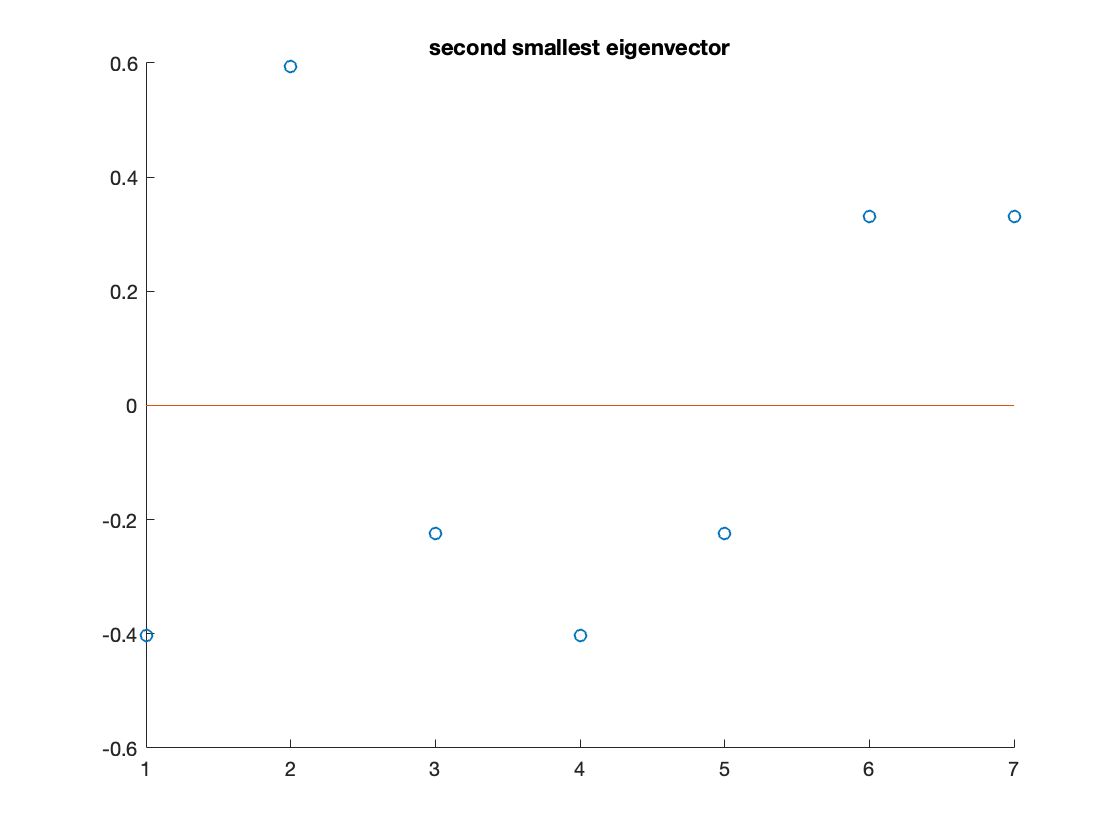

figure
hold on
title('second smallest eigenvector')
scatter([1 2 3 4 5 6 7], U(:, 2))
plot([0 0 0 0 0 0 0])

so positive entries can be one partition (1, 3, 4, 5), negative can be another partition (2, 6, 7)

3d) $x^TLx$ is equal to the sum of distances that we are trying to minimize. Then using the eigenvectors and eigenvalues of L, $x^TLx=x^T\lambda x$, so to minimize, we want the smallest possible eigenvalue which we can find with the inverse power method. And then since the absolute smallest will just be 0 with an eigenvector of 1s and won't actually partition our network, we'll find the 2nd smallest eigenvalue to actually start to partition the network.

## 4

% for any specified alpha
alpha = rand(1);

A=[-2.03,-4.73,-6.71;
    -4.73,0.767,-0.901;
    -6.71,-0.901,7.27];
[n, ~] = size(A);

% using shifted inverse power method
shifted_A = A-(alpha.*eye(n));
v=ones(n, 1);
for i=1:1:50
    v=shifted_A^(-1)*v;
    v=v./norm(v);
end
disp('closest eigenvalue:')

closest eigenvalue:


lambda = A*v./v;
disp(lambda(1,1))

    3.0016



With $A-\alpha I$, its eigenvectors will have eigenvalues of $\lambda - \alpha I$. So $(A-\alpha I)e_k=(\lambda - \alpha I)e_k$. Therefore, $(\lambda - \alpha I)$ will be the smallest eigenvector when $\lambda = \alpha I$. We can use the inverse power method to find the eigenvector for when $(\lambda - \alpha I)$is smallest and find $\lambda$.

% for alpha = -7 and 10 iterations
alpha = -7;

A=[-2.03,-4.73,-6.71;
    -4.73,0.767,-0.901;
    -6.71,-0.901,7.27];
[n, ~] = size(A);

% using shifted inverse power method
shifted_A = A-(alpha.*eye(n));
v=ones(n, 1);
v=shifted_A^(-10)*v;
disp('closest eigenvalue:')

closest eigenvalue:


lambda = A*v./v;
disp(lambda(1,1))

   -7.9961



disp('corresponding eigenvector:')

corresponding eigenvector:


disp(v./norm(v))

    0.7978
    0.4695
    0.3784




% comparing with Matlab calculated eigenvalues
[V, D]=eig(A)

V =    -0.7978    0.3430    0.4959
   -0.4695   -0.8694   -0.1540
   -0.3784    0.3557   -0.8546


D =    -7.9961         0         0
         0    3.0016         0
         0         0   11.0015


-7.9961 is in fact an eigenvalue of A and it's corresponding eigenvector is along the same vector as found with Matlab's eig() function.